# Estimate drainage time for southern highlands aquifer

clc, clear
set_demo_defaults
yr2s = 60^2*24*365.25; % seconds per year
R_mars = 3389508; % [m] Mars' mean radius 
g_mars = 3.711;   % [m/s^2] grav. acceleration on Mars
rho = 1e3;      % [kg/m^3] desity of water 
mu = 1e-3;      % [Pa s] water viscosity

Use numerical solution to estimte a drainage time for the southern highlands aquifer

### Guess-timate the physical properties

#### Fit porosity exponent, m

Here we fit the exponent for the porosity power-law, $\phi(z) = \phi_0 z^m$, to the exponential solution, $\phi(d) = \phi_s\mathrm{e}^{-d/d_0}$, used by Clifford and Parker (2001). Here $d$ is the depth beneath the surface and $z = d_\mathrm{max}-d$, where $d_\mathrm{max}$ is the maximum depth of the aquifer. Hence our model assumed thate $\phi$ becomes zero as $d_\mathrm{max}$, unlike the exponential model. As such the power-law model has three free parameters the coefficient $\phi_0$, the exponet $m$ and finite aquifer depth $d_\mathrm{max}$. We choose $d_\mathrm{\max}$ adetermine the remaining paramters by matching the porosity of the exponetial model at $d=0$ and $d=d_\mathrm{max}/2$ and obtain

$m=\frac{d_\mathrm{max}}{2 d_0 \log(2)}$ and $\phi_0 = \frac{\phi_s}{d_\mathrm{max}^m}$.

The exonent $m$ is independent of the surface porosity $\phi_s$, so that we cavary $\phi_s$ without changing $m$. For and aquifer of $d_\mathrm{max}=10$ km a fitting the porosity at a depth of $d_\mathrm{max}/2$ we obtain $m\approx 2.5$. The resulting curves for the porosity are shown the figure. Perhaps a better choice would be to fit $\phi_0$ and $m$ to match $\phi_s$ and the total pore volume.

dmax = 10e3; % [km] max. aquifer depth
d0 = 2.8375e3;  % decay depth

phi_clifford = @(d,phi_s,d0) phi_s*exp(-d/d0);
phi_s_min = 0.3;
phi_s_max = 0.5;


m_best = dmax/(2*d0*log(2))

m_best = 2.5422

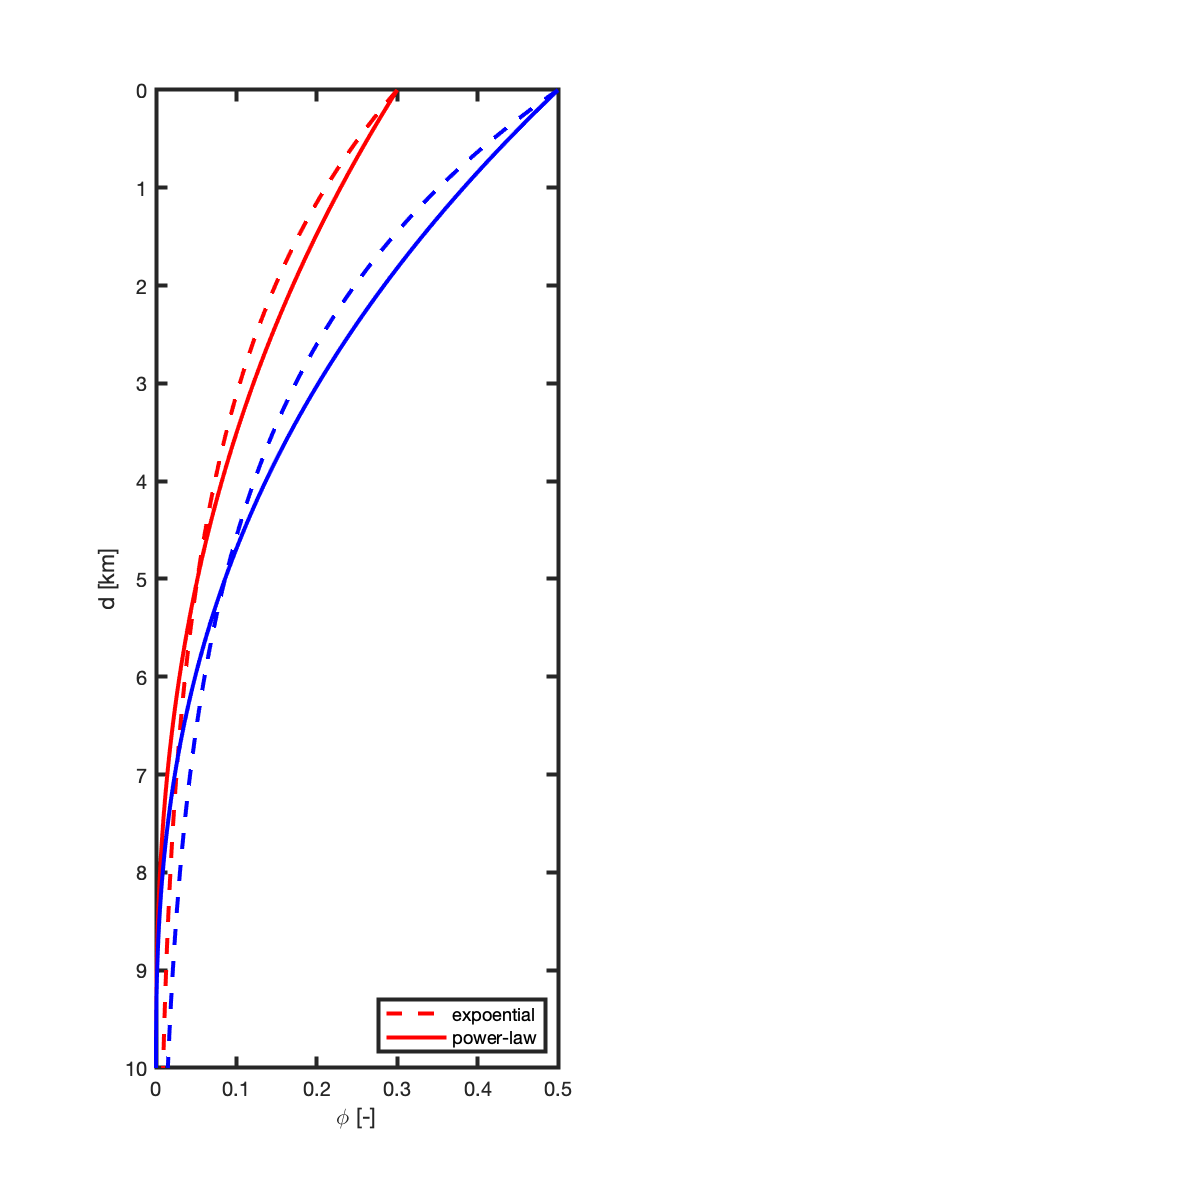

phi0_best = @(phi_s,m) phi_s/(dmax^m);  

phi = @(z,phi0,m_exp) phi0*z.^m_exp;

d = linspace(0,10e3,1e2)';
z = dmax-d;
figure('position',[10 10 600 600])
subplot 121
plot(phi_clifford(d,phi_s_min,d0),d/1e3,'r--'), hold on
plot(phi(z,phi0_best(phi_s_min,m_best),m_best),d/1e3,'r-')
plot(phi_clifford(d,phi_s_max,d0),d/1e3,'b--')
plot(phi(z,phi0_best(phi_s_max,m_best),m_best),d/1e3,'b-')
set(gca,'ydir','reverse')
xlabel '\phi [-]', ylabel 'd [km]'
legend('expoential','power-law','location','southeast')

#### Fit the hydraulic conductivity exponent, n

The power-law for the permeability decay with depth is fit to the Manning and Ingebrisen (1999), which is a power-law decay with depth. As such we simply have


$$k_0 = \frac{k_0^\mathrm{IM}}{(d_\mathrm{max}-10^3)^n}$$


where $k_0^\mathrm{IM}$ is the reference permeability of Manning and  Ingebritsen at 1 km depth.

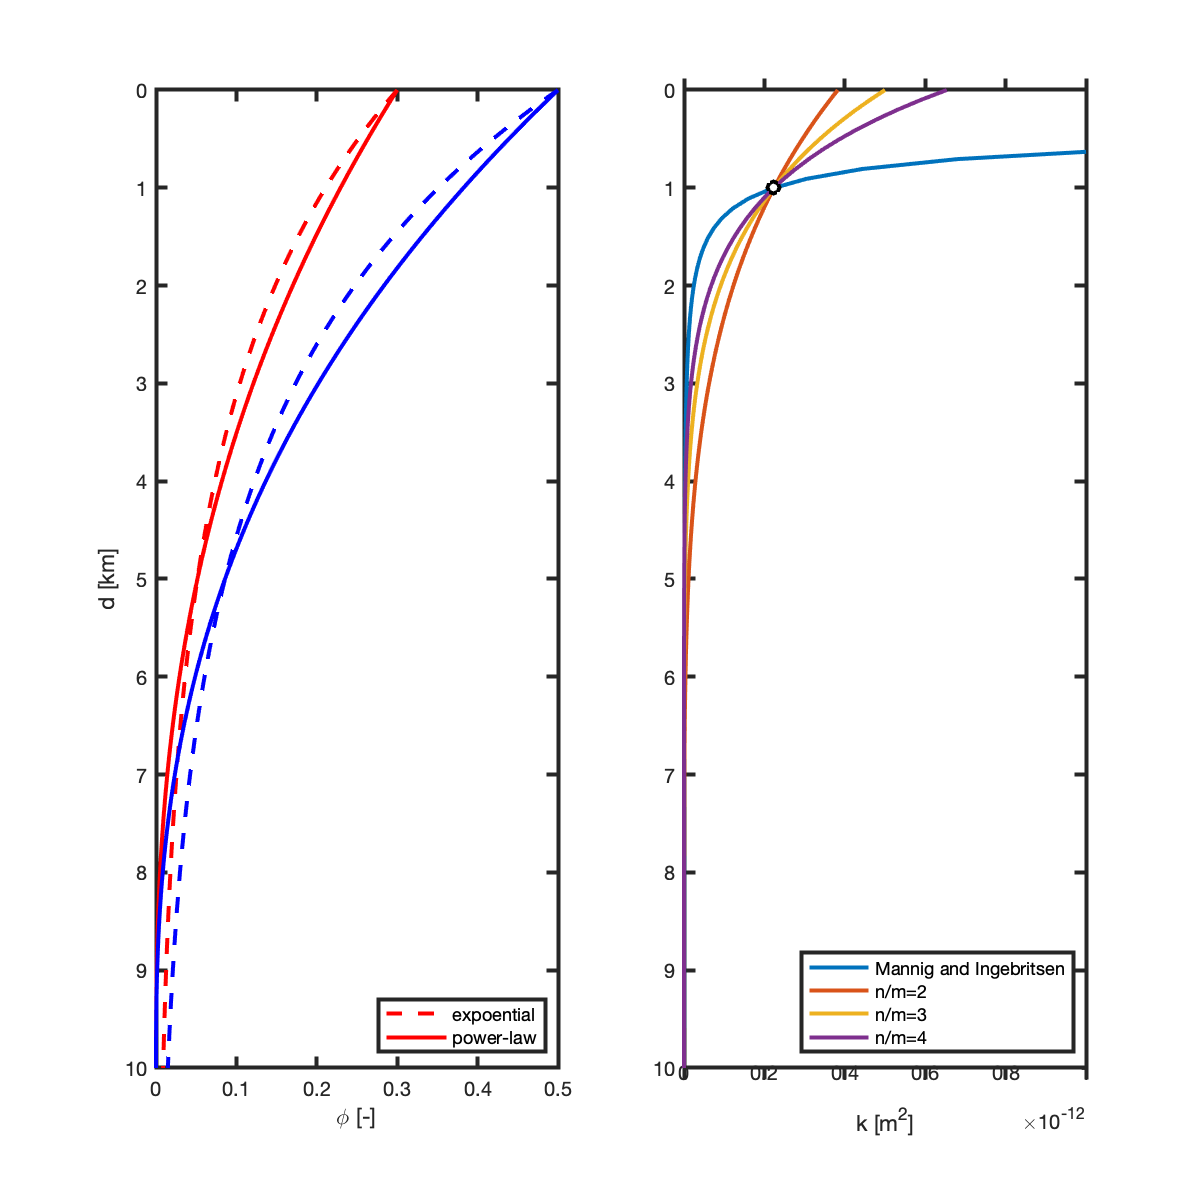

k0_MI = 10^(-12.65); % [m^2] ref. permeability at 1km depth Manning and Ingebritsen (1999)
alpha = 3.2;
k_MI = @(d) k0_MI*d.^(-alpha);

k0 = @(n) k0_MI/(dmax-1e3)^n;
k = @(z,n) k0(n)*z.^n;

subplot 122
plot(k_MI(d/1e3),d/1e3), hold on
plot(k(z,2*m_best),d/1e3)
plot(k(z,3*m_best),d/1e3)
plot(k(z,4*m_best),d/1e3)
plot(k0_MI,1,'ko','markerfacecolor','w','markersize',6)
set(gca,'ydir','reverse')
xlabel 'k [m^2]', 
xlim([0 1e-12])
legend('Mannig and Ingebritsen','n/m=2','n/m=3','n/m=4','location','southeast')

The resulting exponent for the permeability decline is rather large

m_best*2

ans = 5.0844

m_best*4

ans = 10.1688

Based on the permeabilith we can define the hydraulic conductivity 


$$K_0 = \frac{k_0\rho g}{\mu}$$
 

and hydraulic diffusivity


$$D_h = \frac{K_0 (m+1)}{\phi_0(n+1)}$$


K0 = @(n) k0(n)*rho*g_mars/mu;
D_hyd = @(phi_s,m,n) K0(n)*(m+1)/(phi0_best(phi_s,m)*(n+1));

## Estimating drainage timescale for the Martial highlands

theta_bnd = pi-acos(1/3);   % [rad] co-lattitude of the dichotomy boundary
h0 = dmax;                  % [m] initial height of the water table 

To estimate the drainage timescale for the Martial highlands we have the following equations of the spherical shell

PDE: $\phi_0 h^m \frac{\partial h}{\partial t} -\frac{1}{R\sin \theta} \frac{\mathrm{d}}{\mathrm{d}\theta}\left[\sin\theta \frac{K_0}{n+1}\frac{h^{n+1}}{R}\frac{\mathrm{d}h}{\mathrm{d}\theta}\right] = 0$ on $\theta \in \left[0,\,\theta_b\right]$

BC's: $\left.\frac{\mathrm{d}h}{\mathrm{d}\theta}\right|_0 = 0$ and $h(\theta_b)=0$

IC: $h(\theta,0) = h_0$

#### Parameter ranges

Using the fits above the values of $\phi_0$ and $K_0$ in the governing equation, take extreme values

phi0_min = phi0_best(0.3,m_best)

phi0_min = 2.0340e-11

phi0_max = phi0_best(0.5,m_best)

phi0_max = 3.3900e-11

the values for $K_0$ are even more extreme

K0_max = K0(2*m_best)

K0_max = 6.5251e-27

K0_min = K0(4*m_best)

K0_min = 5.1249e-47

and the resulting hydraulic diffusivity is very pooly scaled and can range over more than 10 orders of magnitude

D_hyd_max=D_hyd(0.3,m_best,2*m_best)

D_hyd_max = 1.8677e-16

D_hyd_min=D_hyd(0.5,m_best,4*m_best)

D_hyd_min = 4.7947e-37

### Dimensionless governing equation

As such it is useful to non-dimensionalize the governing equation to improve the scaling. Here we introduce the scales

$h' = \frac{h}{h_0}$,  and $t' = \frac{t}{t_c}$ where we choose the characteristic time $t_c = \frac{\phi_0 R^2(n+1)}{K_0h_0^{n-m+1}}$ and have the dimensionless governing equations

PDE: ${h'}^m \frac{\partial h'}{\partial t} -\frac{1}{\sin \theta} \frac{\mathrm{d}}{\mathrm{d}\theta}\left[\sin\theta {h'}^{n+1}\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right] = 0$ on $\theta \in \left[0,\,\theta_b\right]$

BC's: $\left.\frac{\mathrm{d}h'}{\mathrm{d}\theta}\right|_0 = 0$ and $h'(\theta_b)=0$

IC: $h'(\theta,0) = 1$

The characteristic timescale, $t_c$, indicates the time it takes for the change in head to propagate from the dichotomy to the south pole.  This *propagation timescale* appears to be 40 to 80 million years. The *drainage timescale* is orders-of magnitude longer than this propagation timescale. It is currently unclear (to me) how to properly define the drainage timescale. 

tc = @(phi_s,m,n_mult)  phi0_best(phi_s,m)*R_mars^2*(n_mult*m+1)/(K0(n_mult*m)*h0^(n_mult*m-m+1));

tc_min = tc(0.3,m_best,2)/yr2s

tc_min = 4.6813e+07

tc_max = tc(0.5,m_best,4)/yr2s

tc_max = 8.3822e+07

### Numerical solution

Here we use the values estimated above to compute the timescale for the drainage of the Martian highland aquifer. These are fresh of the press estimates that should be taken with a grain of salt, but it appears that the time to drain 90% of the water is on the order of the age of the solar system! Taken a face value, this would imply that the deep Martian hydrosphere is still adjusting to changes in Mars climate 3 billion years ago. Taking this yet another step further, this means that deep Martian groundwater may have persisted over its entire life time, providing a prodected deep habitat. Of course, this is a good place to remember that we have made many simplifying assumptions :-).

It is encouraging though that the decline follows a power-law and the exponent seems to be predicted by the linear thery of Zheng et al. (2013)! This suggests that the solution on the spherical shell is still self-similar and the theory can be extented. Theoretical results would allow to bracket the decay rates for large range of possible decay rates of porosity and permeability.

n_mult = 3;
m_exp = m_best;
n_exp = n_mult*m_exp;
% Timestepping
tmax = 5e3;
Nt = 2*tmax;
dt = tmax/Nt;

%% Grid and ops
Grid.xmin = 0; Grid.xmax = theta_bnd; Grid.Nx = 300;
Grid.geom = 'spherical_shell'; Grid.R_shell = 1;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
M = Grid.dx/2*abs(G);   % mean operator
fs = zeros(Grid.Nx,1);

%% Jacobian for transient solution
% Function in accumulation term
s  = @(u) u.^m_exp;
ds = @(u) m_exp*u.^(m_exp-1);
S  = @(u) spdiags(s(u),0,Grid.Nx,Grid.Nx);
dS = @(u) spdiags(ds(u),0,Grid.Nx,Grid.Nx);

% Function in flux term
f  = @(u) u.^(n_exp+1)/(n_exp+1);
df = @(u) u.^n_exp;

F  = @(u) spdiags(M*f(u),0,Grid.Nx+1,Grid.Nx+1);
dF = @(u) spdiags(df(u),0,Grid.Nx,Grid.Nx);

% Other 'function matrices'
U  = @(u,uold) spdiags(u-uold,0,Grid.Nx,Grid.Nx);
GU = @(u)      spdiags(G*u,0,Grid.Nx+1,Grid.Nx+1);

% Residual and Jacobian
res = @(u,uold) S(u)*(u-uold) - dt*D*(F(u)*G*u) - dt*fs;
Jac = @(u,uold) dS(u)*U(u,uold) + S(u) - dt*D*(GU(u)*M*dF(u) + F(u)*G);

%% BC's
BC.dof_dir   = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g         = 0;

BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
[B,N,fn] = build_bnd(BC,Grid,I);

%% Initial condition
hD = ones(Grid.Nx,1);
hD(Grid.dof_xmax) = 0;
M = zeros(Nt+1,1); M(1) = sum(hD*Grid.dx);

%% Time integration
kmax = 10; 
tol = 1e-6;

fprintf('Computing transient solution:\n')

Computing transient solution:


for n = 1:Nt
    hDold = hD;
    nres = norm(res(hD,hDold)); ndhD = 1; k = 0;
    while (nres > tol || ndhD > tol) && k < kmax
        dhD = solve_lbvp(Jac(hD,hDold),-res(hD,hDold),B,BC.g,N);
        hD = hD + dhD;
        nres = norm(N'*res(hD,hDold)); ndhD = norm(N'*dhD);
        k = k+1;
%         fprintf('it = %d: nres = %3.2e  ndhD = %3.2e\n',k,nres,ndhD)
        if k == 1; ndhD = 0; end % to allow exit on first iteration
    end
    if k <= kmax; 
%         fprintf('Newton converged after %d iterations\n\n',k)
    else
        error('Newton did not converged after %d iterations\n\n',k)
    end
    tD = n*dt;
    M(n) = sum(hD.^(m_exp+1)/(m_exp+1).*sin(Grid.xc)*Grid.dx);
end
fprintf('Transient solution computed successfully:\n')

Transient solution computed successfully:


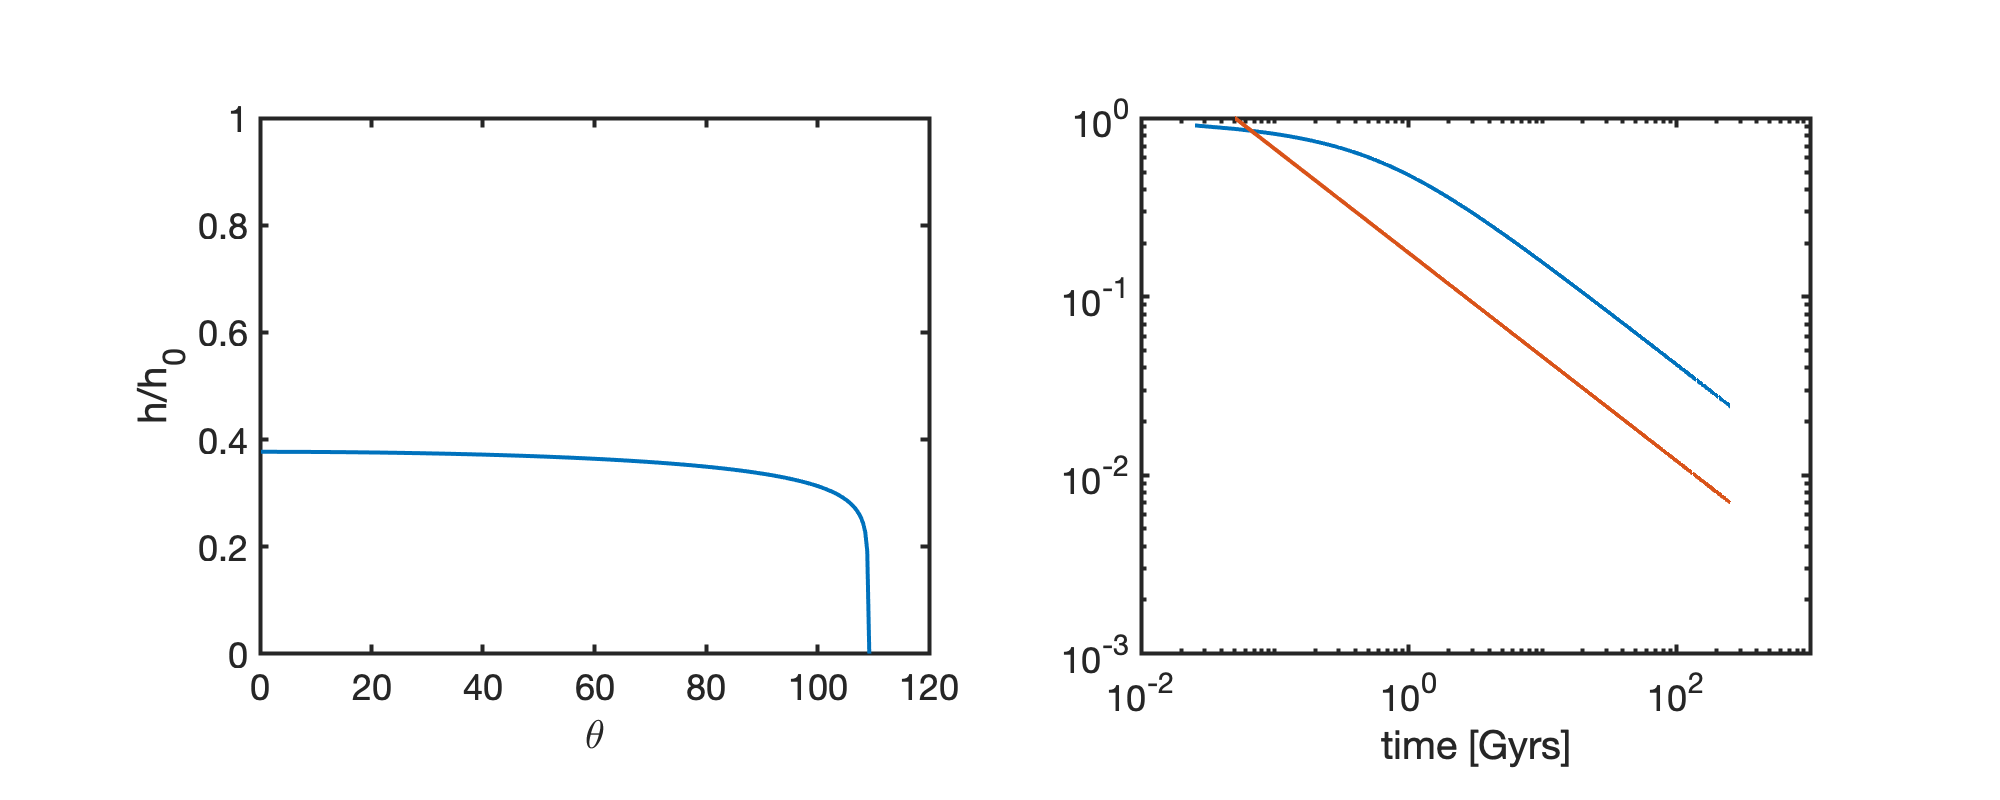


tc_here = tc(0.3,m_exp,n_mult);
M0 = sum(ones(Grid.Nx,1).^(m_exp+1)/(m_exp+1).*sin(Grid.xc)*Grid.dx);
M_theory = @(t) (1./t).^((m_exp+1)/(n_exp-m_exp+1));

figure('position',[10 10 1000 400])
subplot 121
plot(rad2deg(Grid.xc),hD,'-'),
xlabel '\theta', ylabel 'h/h_0'
xlim([0 120])
ylim([0 1])
pbaspect([1 .8 1])

subplot 122
time_vec = [1:Nt+1]*dt;
loglog(time_vec*tc_here/yr2s/1e9,M/M0), hold on
loglog(time_vec*tc_here/yr2s/1e9,M_theory(time_vec))
pbaspect([1 .8 1])
xlim([1e-2,1e3])
ylim([1e-3 1e0])
% legend('numerical','theory')
xlabel 'time [Gyrs]'